# 1 Dimensional Examples

srate = 1000; %Sampling Rate
time = 0:1 / srate: 2-(1/srate);
n = length(time);
Hz = linspace(0, srate, n);

## Pure Sine Wave

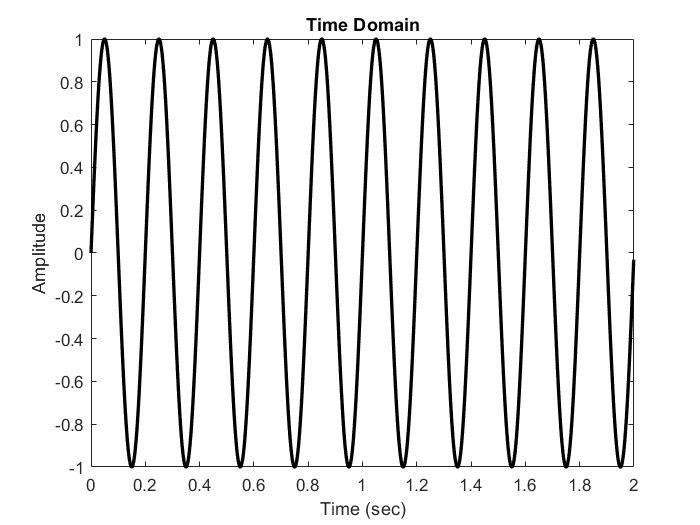


signal = sin(2*pi*5*time);
%compute amplitude spectrum
amp = 2*abs(fft(signal)/n);

%plot in time domain
plot (time, signal, 'k','linew', 2)
xlabel('Time (sec)'), ylabel('Amplitude')
title ('Time Domain')

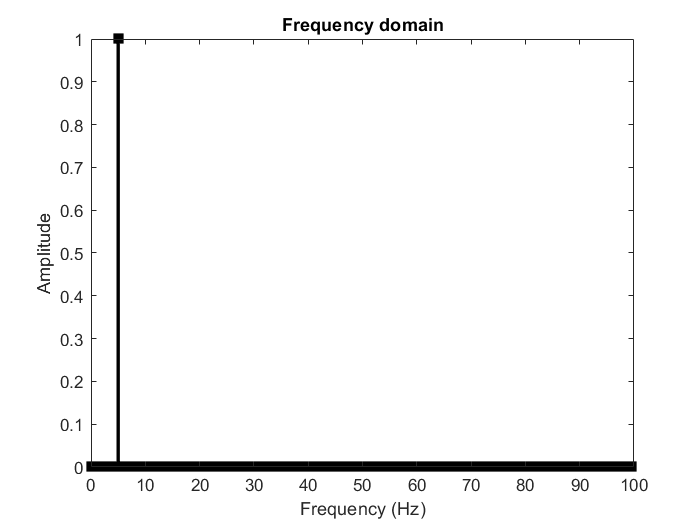

%plot in frequency domain
stem(Hz, amp,'k-s','linew', 2,'markerfacecolor', 'k')
xlim ([0 100])
xlabel('Frequency (Hz)'), ylabel('Amplitude')
title('Frequency domain')

## Multispectral Sine Wave

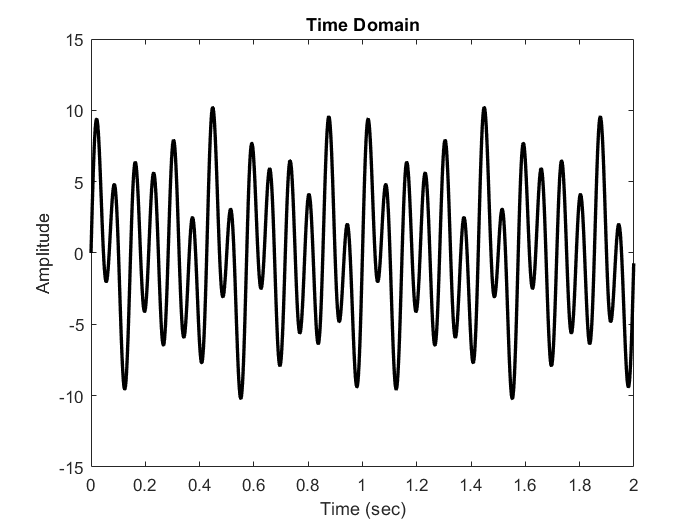


signal = 2*sin(2*pi*5*time)+ 3*sin(2*pi*7*time)+ 6*sin(2*pi*14*time);
%compute amplitude spectrum
amp = 2*abs(fft(signal)/n);

%plot in time domain
plot (time, signal, 'k','linew', 2)
xlabel('Time (sec)'), ylabel('Amplitude')
title ('Time Domain')

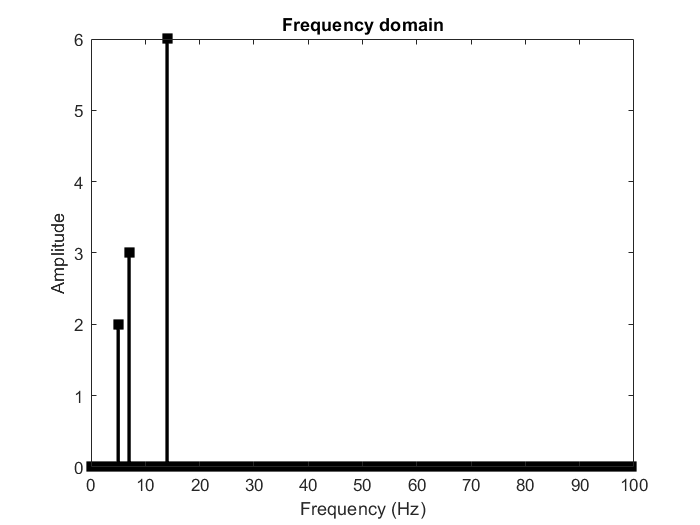

%plot in frequency domain
stem(Hz, amp,'k-s','linew', 2,'markerfacecolor', 'k')
xlim ([0 100])
xlabel('Frequency (Hz)'), ylabel('Amplitude')
title('Frequency domain')

## White Noise

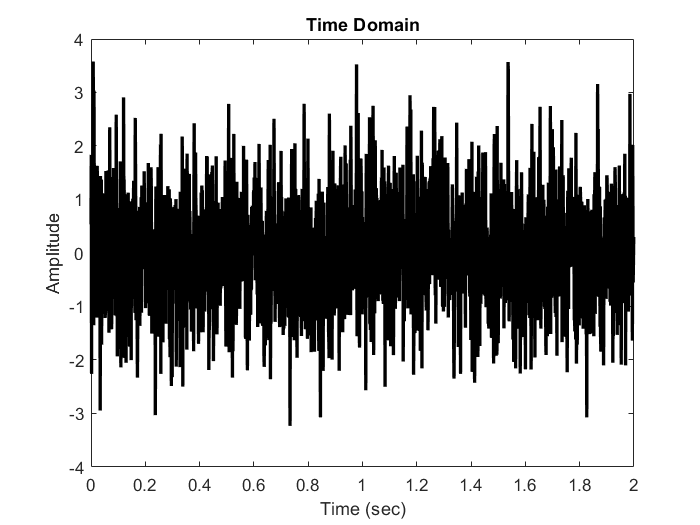

signal = randn(size(time));
%compute amplitude spectrum
amp = 2*abs(fft(signal)/n);

%plot in time domain
plot (time, signal, 'k','linew', 2)
xlabel('Time (sec)'), ylabel('Amplitude')
title ('Time Domain')

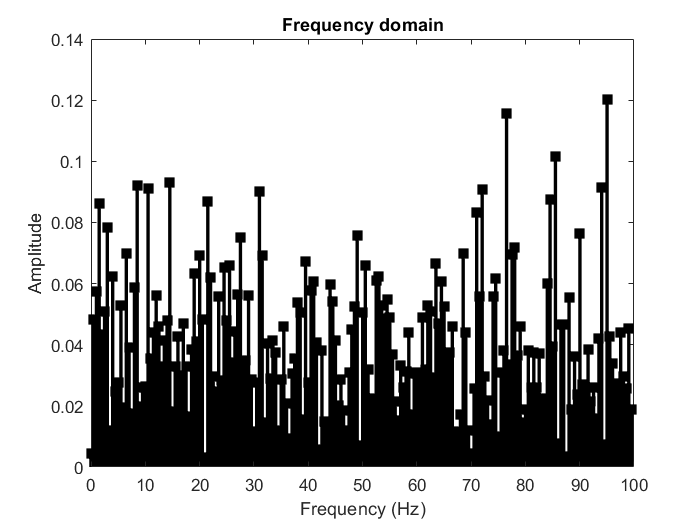

%plot in frequency domain
stem(Hz, amp,'k-s','linew', 2,'markerfacecolor', 'k')
xlim ([0 100])
xlabel('Frequency (Hz)'), ylabel('Amplitude')
title('Frequency domain')

## Brownian Noise (Pink Noise)

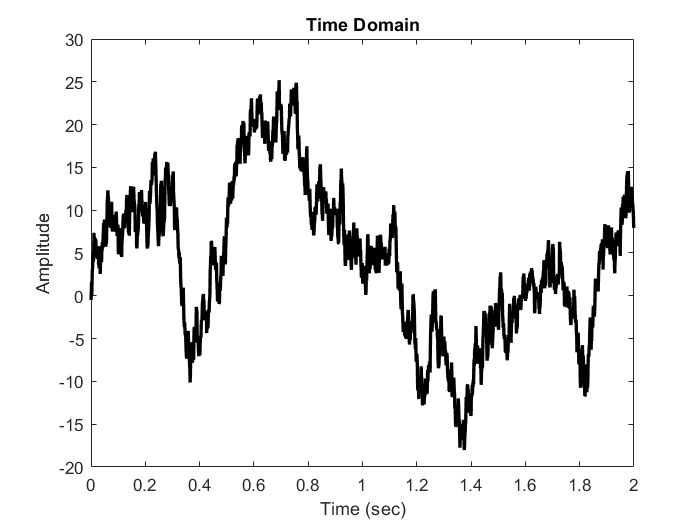

signal = cumsum(randn(size(time))); %cummulative sum 
%compute amplitude spectrum
amp = 2*abs(fft(signal)/n);

%plot in time domain
plot (time, signal, 'k','linew', 2)
xlabel('Time (sec)'), ylabel('Amplitude')
title ('Time Domain')

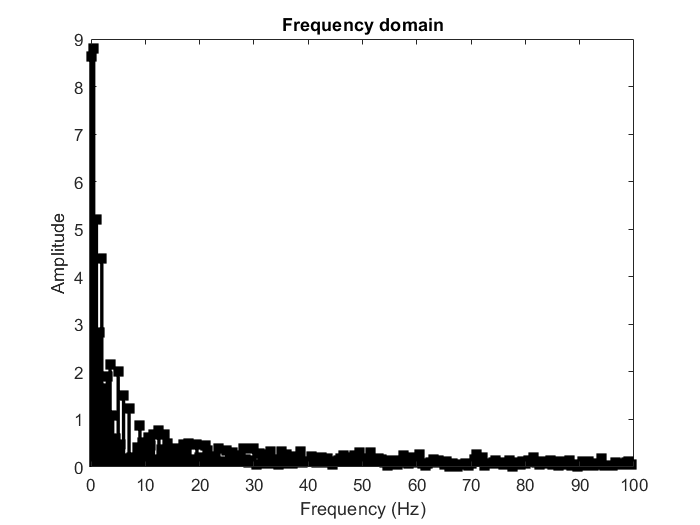

%plot in frequency domain
stem(Hz, amp,'k-s','linew', 2,'markerfacecolor', 'k')
xlim ([0 100])
xlabel('Frequency (Hz)'), ylabel('Amplitude')
title('Frequency domain')

## 1/f Noise

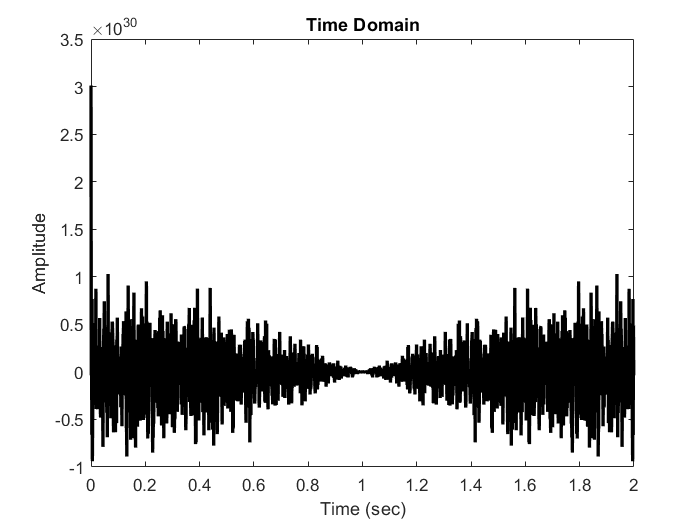

ps = exp (11*2*pi*rand(1,n/2)) .* 0.1+exp(-(1:n/2)/50);
ps = [ps ps(:, end:-1:1)];
signal = real (ifft(ps))*n; 
%compute amplitude spectrum
amp = 2*abs(fft(signal)/n);

%plot in time domain
plot (time, signal, 'k','linew', 2)
xlabel('Time (sec)'), ylabel('Amplitude')
title ('Time Domain')

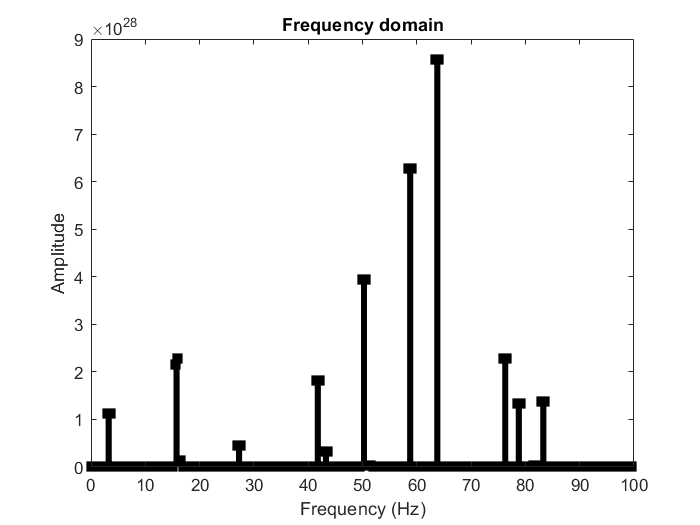

%plot in frequency domain
stem(Hz, amp,'k-s','linew', 2,'markerfacecolor', 'k')
xlim ([0 100])
xlabel('Frequency (Hz)'), ylabel('Amplitude')
title('Frequency domain')

## Square Wave Pulse

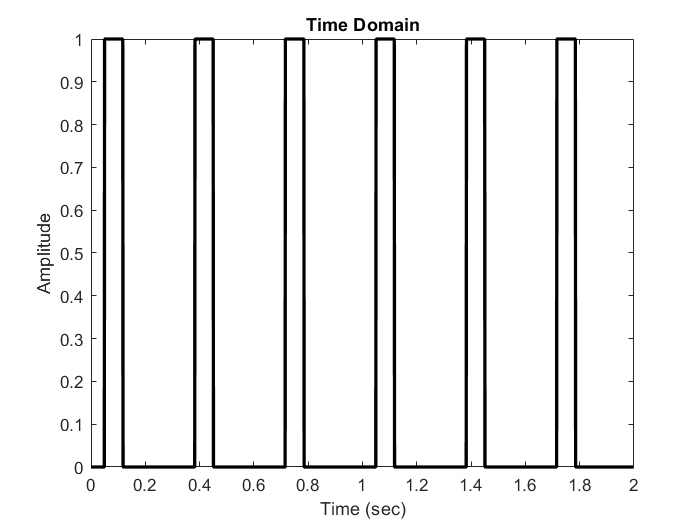

signal = zeros(size(time)); 
signal(sin(2*pi*3*time)>0.8)=1;
%compute amplitude spectrum
amp = 2*abs(fft(signal)/n);

%plot in time domain
plot (time, signal, 'k','linew', 2)
xlabel('Time (sec)'), ylabel('Amplitude')
title ('Time Domain')

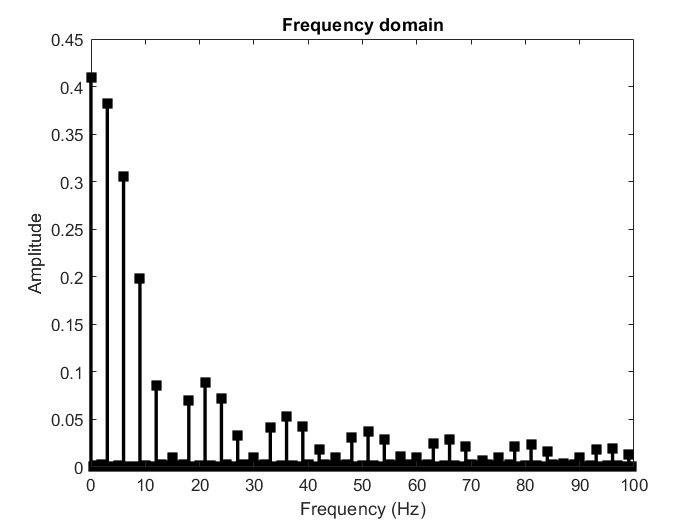

%plot in frequency domain
stem(Hz, amp,'k-s','linew', 2,'markerfacecolor', 'k')
xlim ([0 100])
xlabel('Frequency (Hz)'), ylabel('Amplitude')
title('Frequency domain')

## Amplitude Modulation (AM) Wave

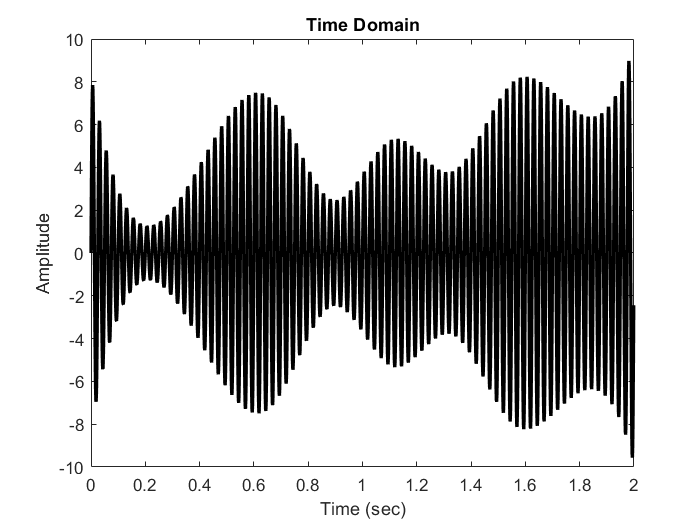

signal = 10*interp1(rand(1,10), linspace(1,10,n), 'spline') .*sin(2*pi*40*time);
%compute amplitude spectrum
amp = 2*abs(fft(signal)/n);

%plot in time domain
plot (time, signal, 'k','linew', 2)
xlabel('Time (sec)'), ylabel('Amplitude')
title ('Time Domain')

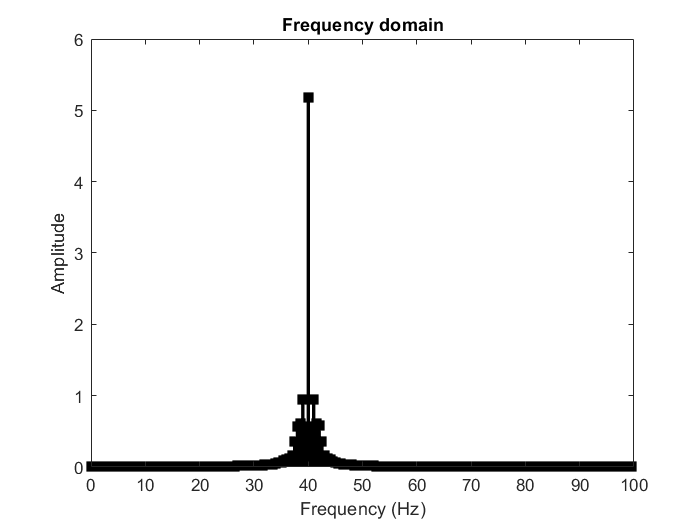

%plot in frequency domain
stem(Hz, amp,'k-s','linew', 2,'markerfacecolor', 'k')
xlim ([0 100])
xlabel('Frequency (Hz)'), ylabel('Amplitude')
title('Frequency domain')


%Notice: Even when we are giving just one frequency (40 Hz), due to fluctuations, the noise around the peak frequency
%(Effect of Non-Stationarities on Signals)

## Frequency Modulation (AM) Wave

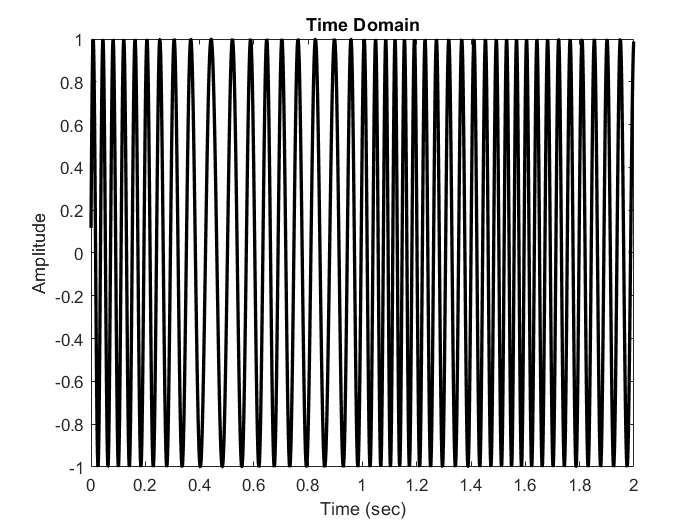

freqmod = 20*interp1(rand(1,10), linspace(1,10,n));
signal = sin(2*pi*(10*time + cumsum(freqmod)/srate));
%compute amplitude spectrum
amp = 2*abs(fft(signal)/n);

%plot in time domain
plot (time, signal, 'k','linew', 2)
xlabel('Time (sec)'), ylabel('Amplitude')
title ('Time Domain')

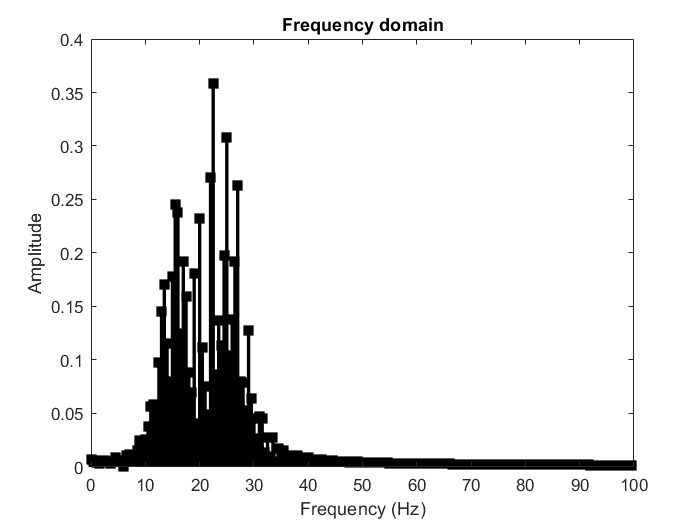

%plot in frequency domain
stem(Hz, amp,'k-s','linew', 2,'markerfacecolor', 'k')
xlim ([0 100])
xlabel('Frequency (Hz)'), ylabel('Amplitude')
title('Frequency domain')